Analysis of Self-Administration training behaviors.

add python script to path

clc; clear;

username = getenv('username');
setenv('PYTHONUNBUFFERED','1'); % doesn't change much, but just-in-case
setenv('path',['C:\Users\' username '\Anaconda3\Library\bin;', getenv('path')]);
% 
% pe=pyenv('Version',['C:\Users\' username '\Anaconda3\envs\test_py36\pythonw.exe'],...         
%          'ExecutionMode','InProcess');
     
% add to Python path
pypath = 'D:\\Matlab_scripts\\WangLab\\SA_training';
if count(py.sys.path, pypath) == 0
    insert(py.sys.path,int32(0), pypath)
end
disp(pypath)

D:\\Matlab_scripts\\WangLab\\SA_training


Select the data folder for analysis

datafolder = 'H:\\Data\\SA_training\\SA_75\\Acquisition'

datafolder = 'H:\\Data\\SA_training\\SA_75\\Acquisition'

cd(datafolder)
% files = dir('*.txt');
% data = [];
% for i = 1:length(files)
%     file = files(i).name;
%     df = py.medpc_read.medpc_readdata(file);
%     temp = df2t(df);
%     data = [data; temp];
% end
data = py.medpc_read.medpc_preprocess(datafolder);

Error using pathlib>stat
Python Error: OSError: [WinError 123] The filename, directory name, or volume label syntax is incorrect: 'H:\\Data\\SA_training\\SA_75\\Acquisition\\sa75_H:\\Data\\SA_training\\SA_75'

Error in pathlib>is_dir (line 1415)

Error in common>check_parent_directory (line 567)

Error in <a href=

% timestamp = py.medpc_read.medpc_readtimestamps('2023-02-06_14h58m_Subject SA63.txt');


summarydata = df2t(data);
files = dir([datafolder, '\*.txt']);
timestamps = [];
for i = 1:length(files)
    temp = struct(py.medpc_read.medpc_readtimestamps(files(i).name));
    timestamps(i).cue = [0, double(temp.G.values)];
    timestamps(i).back_lever = double(temp.L.values);
    timestamps(i).back_lever(find(timestamps(i).back_lever ==0)) = [];
    timestamps(i).front_lever = double(temp.M.values);
    timestamps(i).front_lever(find(timestamps(i).front_lever ==0)) = [];
    timestamps(i).reward = double(temp.W.values); 
    timestamps(i).reward(find(timestamps(i).reward ==0)) = [];
end
save('SA74_Behavior_Acquisition_data.mat', 'summarydata', 'timestamps')

data_sum{1} = subdata;
data_sum{2} = subdata;

Plot 2 animal data

SA_behavioral_Plot_2A(data_sum)

Plot one animal data

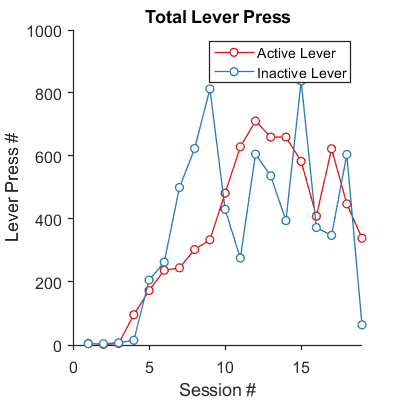

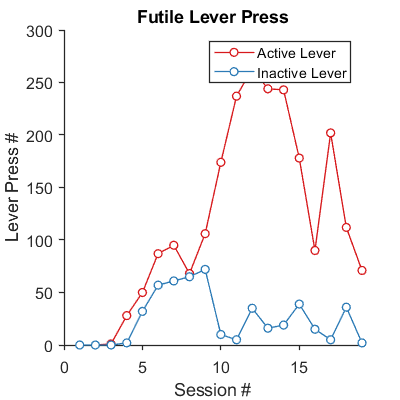

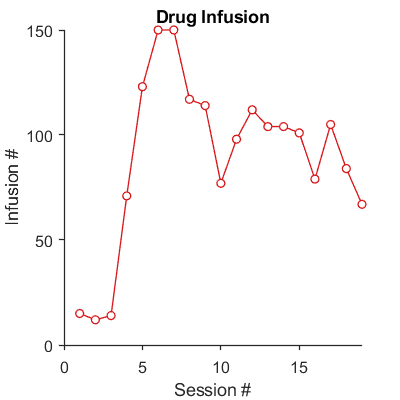

SA_behavioral_Plot_1A(summarydata)

Show one example session of lever pressing

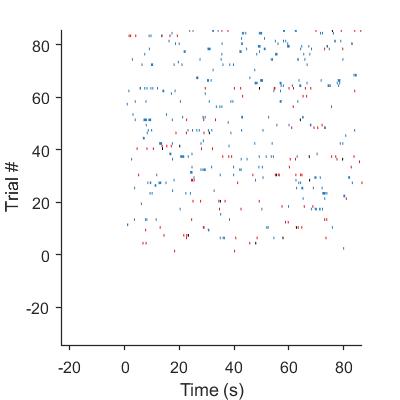

ans =    18.2300  194.6700  124.9200    6.6900  152.5500   22.6100   14.3600  274.0700    7.6400   12.9700  163.7900   58.7700   24.4500  122.9200  102.2000  293.2000   34.6600   57.4900   94.0900   24.9400   80.9900  121.0900   97.1500  296.2500  144.4800  155.9700   41.2900   24.4300  200.1100    5.1100  105.2700  144.8800   60.1600  191.8000   85.8000   60.4800   35.8500  106.8400  167.2300    4.5200   13.6700  121.6600  200.1100   99.4300  137.9100   18.7400  102.1200   61.0700   72.1300  134.0400


i = 15;
cue = timestamps(i).cue;
activeLever = timestamps(i).back_lever;
inactiveLever = timestamps(i).front_lever;
reward = timestamps(i).reward;
SA_perievent_raster_plot(cue,inactiveLever, activeLever, reward)